## k-Nearest Neighbours (kNN) Model Selection

Sin Sze Li 210035720

### 1) Data preparation

% Load the training data
tblTrain = readtable('training_set.csv');

% Select related rows and columns
tblTrain = tblTrain(:, 2:end);
head(tblTrain)

ans = 8×11 table
    baseline_value    accelerations    fetal_movement    uterine_contractions    light_decelerations    severe_decelerations    prolongued_decelerations    abnormal_short_term_var    abnormal_short_term_var_mean    abnormal_long_term_var    fetal_health
    ______________    _____________    ______________    ____________________    ___________________    ____________________    ________________________    _______________________    ____________________________    ______________________    ____________

         147                  0                0                0.002                   0.002       


% Split the data to features and classes
Train_X = tblTrain(: ,1:end-1);             %Training Features
Train_y = tblTrain(: ,end);                 %Training Classes

% Normalize the features
Train_X = normalize(Train_X, 'range')

Train_X = 2316×10 table
    baseline_value    accelerations    fetal_movement    uterine_contractions    light_decelerations    severe_decelerations    prolongued_decelerations    abnormal_short_term_var    abnormal_short_term_var_mean    abnormal_long_term_var
    ______________    _____________    ______________    ____________________    ___________________    ____________________    ________________________    _______________________    ____________________________    ______________________

       0.75926                 0                 0              0.14286                0.13333                   0                           0                 

### 2) Bayesian optimization

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.10515 |     0.51967 |     0.10515 |     0.10515 |           59 |  mahalanobis |
|    2 | Best   |     0.10046 |     0.12847 |     0.10046 |      0.1009 |           38 |    chebychev |
|    3 | Best   |    0.093245 |     0.10563 |    0.093245 |    0.093633 |           35 |    euclidean |
|    4 | Accept |     0.10104 |     0.16324 |    0.093245 |    0.094287 |           85 |   seuclidean |
|    5 | Best   |    0.089249 |      0.1115 |    0.089249 |    0.091599 |           33 |    euclidean |
|    6 | Best   |    0.087371 |    0.098153 |    0.087371 |    0

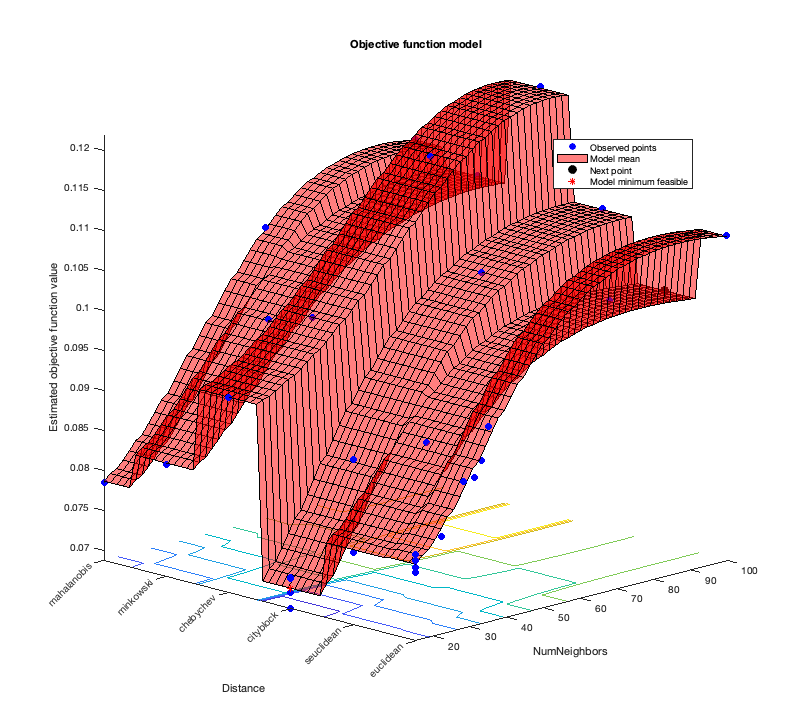

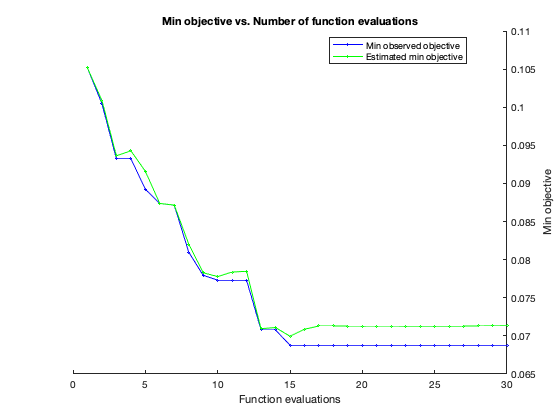


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 18.5623 seconds
Total objective function evaluation time: 3.7556

Best observed feasible point:
    NumNeighbors    Distance 
    ____________    _________

         15         cityblock

Observed objective function value = 0.068779
Estimated objective function value = 0.071331
Function evaluation time = 0.10377

Best estimated feasible point (according to models):
    NumNeighbors    Distance 
    ____________    _________

         15         cityblock

Estimated objective function value = 0.071331
Estimated function evaluation time = 0.10256



rng('default') %for reproducibility

% Hyperparameters for optimization and their ranges
NumNeighbors = optimizableVariable('NumNeighbors',[15, 100],'Type','integer');
Distance = optimizableVariable('Distance',{'euclidean' 'seuclidean' 'cityblock' 'chebychev' 'minkowski' 'mahalanobis'},'Type','categorical');
knnhyperparamters = [NumNeighbors,Distance];

% Optimize the hyperparameters by bayesian optimizer
% f1_knn_objective can be found at the end of the script
results = bayesopt(@(params)f1_knn_objective(params,Train_X,Train_y),knnhyperparamters,...
    'AcquisitionFunctionName','expected-improvement-plus','Verbose',1);

Therefore, the best combination of hyperparameters is NumNeighbors = 15 and Distance = 'cityblock'. These hyperparameters are passed to the final model.

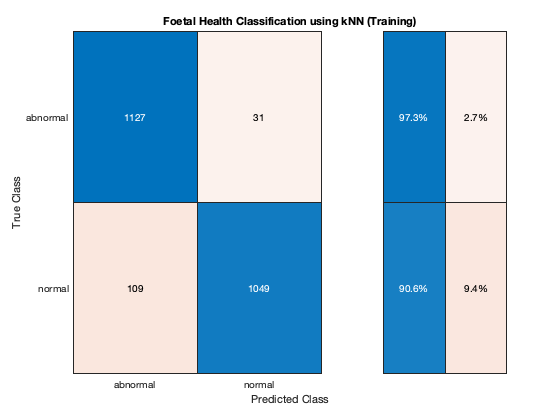

% Train the best model according to bayesian optimizer
Model_knn = fitcknn(Train_X,Train_y,'NumNeighbors', 15, 'Distance', 'cityblock','ClassNames',{'abnormal', 'normal'}); 


% Predict the labels and posterior probabilities of each class 
[label_knn, score_knn] = predict(Model_knn, Train_X);

% Confusion matrix
figure()
cm=confusionchart(table2cell(Train_y),label_knn);
cm.RowSummary = 'row-normalized';
cm.Title = 'Foetal Health Classification using kNN (Training)';


% Define the TP, TN, FP and FN
[confMat,order] = confusionmat(table2cell(Train_y),label_knn);
TP = confMat(1, 1); 
TN = confMat(2, 2);
FP = confMat(2, 1);
FN = confMat(1, 2);

% Calculate the accuracy, recall, precision and F1 score
acc = (TP+TN)/(TP+TN+FP+FN)

acc = 0.9396

recall = TP/(TP+FN)

recall = 0.9732

precision = TP/(TP+FP)

precision = 0.9118

F1 = 2*recall*precision/(recall+precision)

F1 = 0.9415


table_result = table(acc',recall',precision',F1', 'VariableNames', {'Accuracy','Recall','Precision','F_1'});
display(table_result)

table_result = 1×4 table
    Accuracy    Recall     Precision      F_1  
    ________    _______    _________    _______

    0.93955     0.97323     0.91181     0.94152


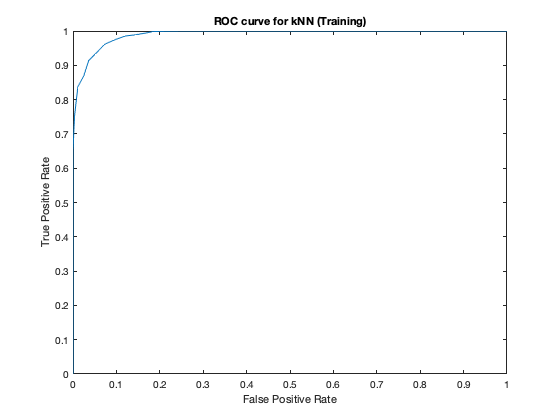


% ROC curve
true_class_knn = table2array(Train_y) =="abnormal";
true_class_knn = double(true_class_knn);
[X_knn Y_knn T_knn AUC_knn] = perfcurve(true_class_knn, score_knn(:, 1), 1);

figure;
plot(X_knn, Y_knn);
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC curve for kNN (Training)');

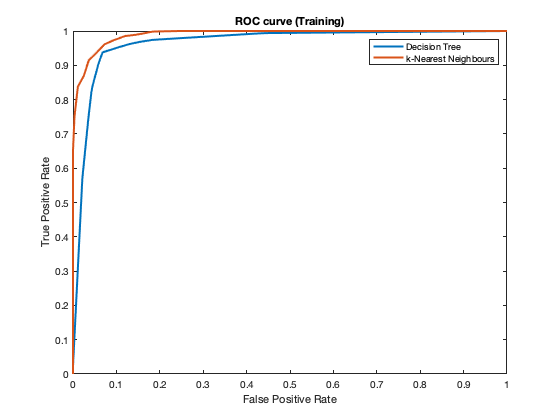

% Plot two ROC curve on the same graph
figure();
plot(X, Y, 'LineWidth', 2)
hold on;
plot(X_knn, Y_knn, 'LineWidth', 2)
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC curve (Training)');
legend('Decision Tree', 'k-Nearest Neighbours')

### 3) Save the trained model and testing set to .mat file (commented out to avoid saving file repeatedly)

% % Load the testing set
% tblTest = readtable('testing_set.csv');
% 
% % Select related rows and columns
% tblTest = tblTest(:, 2:end);
% 
% % Split the data to features and classes
% Test_X = tblTest(: ,1:end-1);             %Training Features
% Test_y = tblTest(: ,end);                 %Training Classes
% 
% % Normalize the features
% Test_X_norm = normalize(Test_X, 'range');
% 
% 
% save('kNN_Final_Model.mat', 'Model_knn', 'Test_X_norm', 'Test_y', 'Test_X')

### 4) Function

function f1 = f1_knn_objective(params,X,Y)
        KNN=fitcknn(X,Y,'CrossVa', 'on', 'NSMethod', 'exhaustive', 'NumNeighbors',params.NumNeighbors, 'Distance', char(params.Distance));
        %Calculate F1 of each combination
        Predicted=kfoldPredict(KNN);
        confMat=confusionmat(table2cell(Y),Predicted);   
        recall=confMat(1,1)/sum(confMat(1,:));
        precision=confMat(1,1)/sum(confMat(:,1));
        f1 = 2*recall*precision/(recall+precision);
        f1=1-f1;
end